clear;
file = 'potdng';

%ims = zeros(4, 2000-16, 1500-16, 3, 'single');
ims = zeros(4, 2000-24, 1500-24, 3, 'single');

for x=0:1:3
    deg = num2str(45 * x);
    ims(x+1, :, :, :) = imread(strcat('cut/', file, deg, '.tif'));
end
clear x;
clear deg;

ims = rgb2lin(ims / 255.0);
imsfft = fft(ims, 4, 1) * 0.5;
clear ims;

imsfftmean = squeeze(imsfft(1, :, :, :)) * 0.5; % 0.5 * Diffuse + 0.5 * Perp + 0.5 * Parallel
imsfftcosine = squeeze(abs(imsfft(2, :, :, :))); % 0.5 * (Perp - Parallel)
clear imsfft;

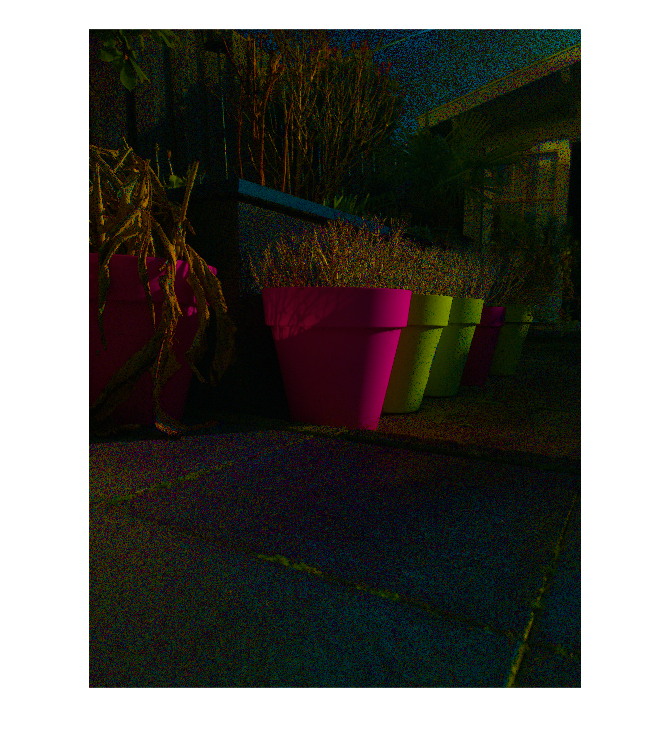

ProjOntoCosineIter = min(imsfftmean ./ max(0.001, imsfftcosine), [], 3);
imshow(lin2rgb(imsfftmean - (ProjOntoCosineIter .* imsfftcosine)));

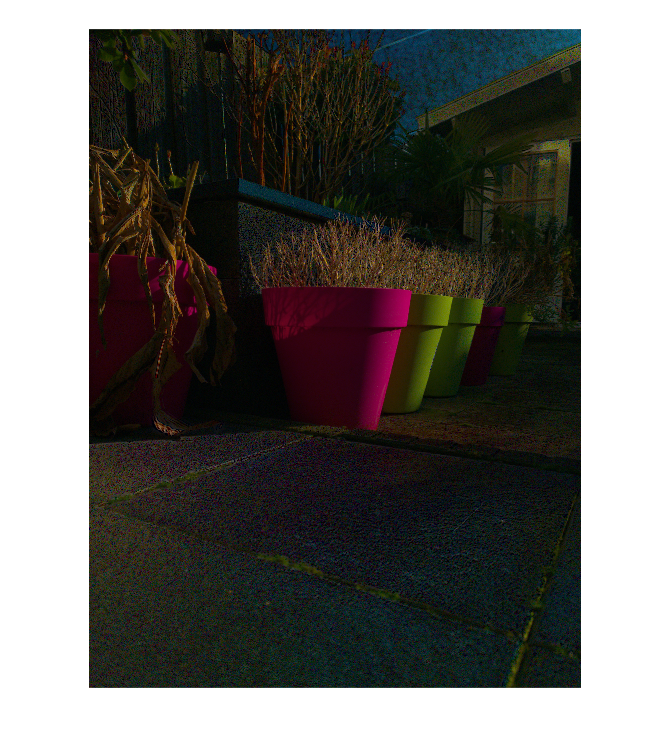


ProjOntoCosineIter = gpuArray(ProjOntoCosineIter);
MeanRGB = gpuArray(imsfftmean);

[qytotal, qxtotal] = size(ProjOntoCosineIter);
qypart = qytotal / 4;
qxpart = qxtotal / 4;

IterCount = 1;
for i = 1:IterCount
    % Left.
    %ProjOntoCosineIter(1:end, 1:(end-1)) = min(ProjOntoCosineIter(1:end, 1:(end-1)), ProjOntoCosineIter(1:end, 2:end));
    % Right.
    %ProjOntoCosineIter(1:end, 2:end) = min(ProjOntoCosineIter(1:end, 1:(end-1)), ProjOntoCosineIter(1:end, 2:end));
    % Up.
    %ProjOntoCosineIter(1:(end-1), 1:end) = min(ProjOntoCosineIter(1:(end-1), 1:end), ProjOntoCosineIter(2:end, 1:end));
    % Down.
    %ProjOntoCosineIter(2:end, 1:end) = min(ProjOntoCosineIter(1:(end-1), 1:end), ProjOntoCosineIter(2:end, 1:end));
    
    % Do the bilateral update based on Fresnel ratios at once.
    ProjOntoCosineIter = bilateralx(ProjOntoCosineIter, MeanRGB, 3.0, 0.05, @(x) ((x + 0.05) .^ -3.0));

    % Divide line-intersection in 16 sub-parts for memory usage.
    for qy = 0:3
        yoffset = qypart * qy;
        for qx = 0:3
            xoffset = qxpart * qx;
            result = linebilateralx(qypart, qxpart, yoffset, xoffset);
            ProjOntoCosineIter((yoffset+1):(yoffset+qypart), (xoffset+1):(xoffset+qxpart)) = result;
            clear result;
        end
    end
end

ProjOntoCosineIter = gather(ProjOntoCosineIter);

imshow(lin2rgb(imsfftmean - (ProjOntoCosineIter .* imsfftcosine)));

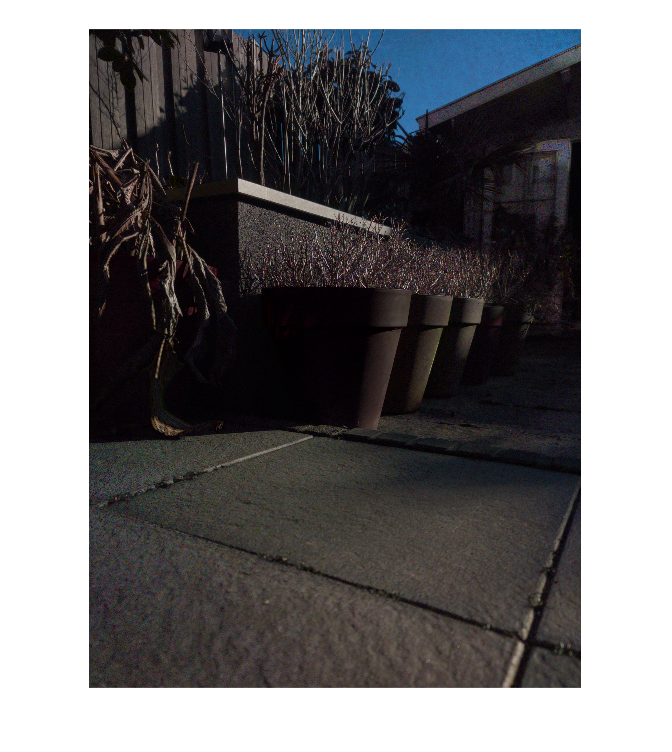

%imshow(lin2rgb(imsfftmean));
imshow(lin2rgb(ProjOntoCosineIter .* imsfftcosine));

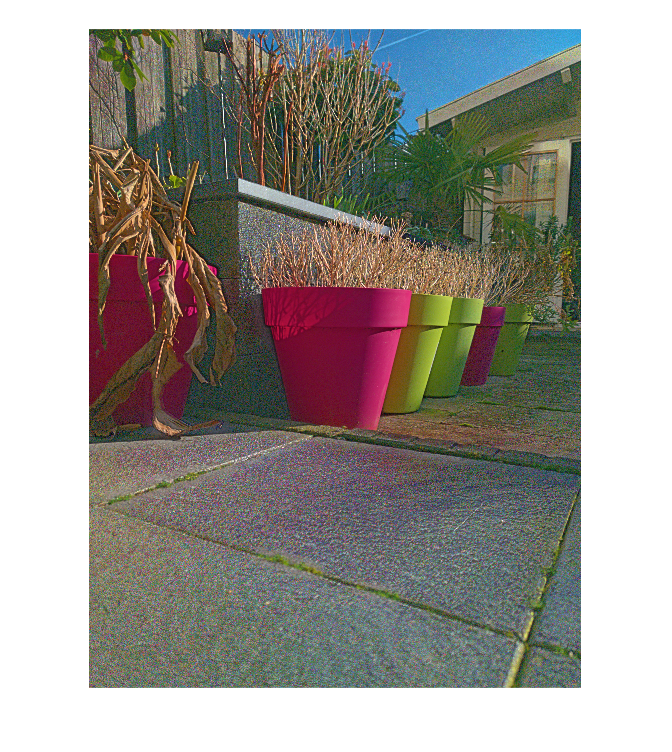

Specular = ProjOntoCosineIter .* gpuArray(imsfftcosine);
Diffuse = gpuArray(imsfftmean - Specular);

imggpu = max(0, Diffuse);
imgbil = bilateral(imggpu, 4.0, 0.15);

imghsv = rgb2hsv(imggpu);
imgbilhsv = rgb2hsv(imgbil);

imghsvbase = imgbilhsv(:, :, 3);
imghsvdetail = imghsv(:, :, 3) ./ imghsvbase;

imghsvcombine = imghsv;
imghsvcombine(:, :, 3) = tonemap(imghsvbase, imghsvdetail, 0.45, 1.45);

imshow(lin2rgb(gather(hsv2rgb(imghsvcombine) + Specular)));